# Demonstrate SEE-SII pandels. Added Current Checking

## 1. Select background parameters

clear

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.020 0.024 0.028];
S_IItest = [0.06  0.09  0.12  0.15  0.18];
Panel1 = length(S_EEtest); Panel2 = length(S_IItest);
S_ElgnInd = 4;
S_IlgnInd = 4; % $(seq 2 4)
rI_L6Ind = 6;  % 3 6

## 2. Rate Contour lines

figure('Name','Contour')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
        CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrI,[8  15],'ShowText','on','color','b');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

Check blowups

% figure('Name','Failure') SampleNum = ContourData_Base.SampleNum; for
% S_IlgnInd = 1:ContourData_Base.PanelNum1
%     S_Ilgn = ContourData_Base.S_Ilgntest(S_IlgnInd); for rI_L6Ind =
%     1:ContourData_Base.PanelNum2
%         rI_L6 = ContourData_Base.rI_L6test(rI_L6Ind);
%
%         load(sprintf('ContourData_S_EE=0.024_S_Elgn=%.3f_7D_HPC_PX%d_PY%d.mat',S_Elgn,S_IlgnInd,rI_L6Ind),'ContourData_7D')
%
%         subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2,
%         rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
%         %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
%         rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1)) CurrentBlowup =
%         squeeze(ContourData_7D.FailIndi(:,: ));
%
%
%
%         imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentBlowup);
%
%         S_Ilgntxt = sprintf('%.3f',S_Ilgn); rI_L6txt =
%         sprintf('%.3f',rI_L6); title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6}
%         = ' rI_L6txt ]) xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as
%         y*S_{EE}') set(gca,'Ydir','Normal') %xlim([0.06 0.5])
%     end
% end


## 3. Firing rate heapmap

figure('Name','Ratemap')
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        subplot(Panel1*2, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); CurrentFrE(CurrentFrE<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 15])
        
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                         CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        
        subplot(Panel1*2, Panel2, S_IIInd+Panel2*(S_EEInd-1)+Panel1*Panel2)
        %     subplot(ContourData_7D.PanelNum2*2, ContourData_7D.PanelNum1,
        %     rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1)+...
        %                                                                    
        %                                                                    ContourData_7D.PanelNum2
        %                                                                    *
        %                                                                    ContourData_7D.PanelNum1)
        hold on
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: )); CurrentFrI(CurrentFrI<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrI)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 40])
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrI,[10 18],'ShowText','on','color','k');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

Fig1 = figure('Name','WhitenHeatmap','units','normalized','outerposition',[0 0 1 1]);
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 15])
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

And frI/frE

Fig2 = figure('Name','Fr Prop','units','normalized','outerposition',[0 0 1 1]);
for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                  S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end
        
        subplot(Panel1, Panel2, S_IIInd+Panel2*(S_EEInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        Prop = CurrentFrI./CurrentFrE;
        Prop(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        Prop(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, Prop)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 9])
        
        
        hold off
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
                       S_EE,        S_II,        S_Elgn,        S_Ilgn))
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

Save figures

MF_7Dpath = [FigurePath '\MF_7D_fine\'];
FigName1 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rE',...
                             S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
FigName2 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rRatio',...
                             S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
savefig(Fig1,[MF_7Dpath FigName1 '.fig']);
savefig(Fig2,[MF_7Dpath FigName2 '.fig']);

Print Figs

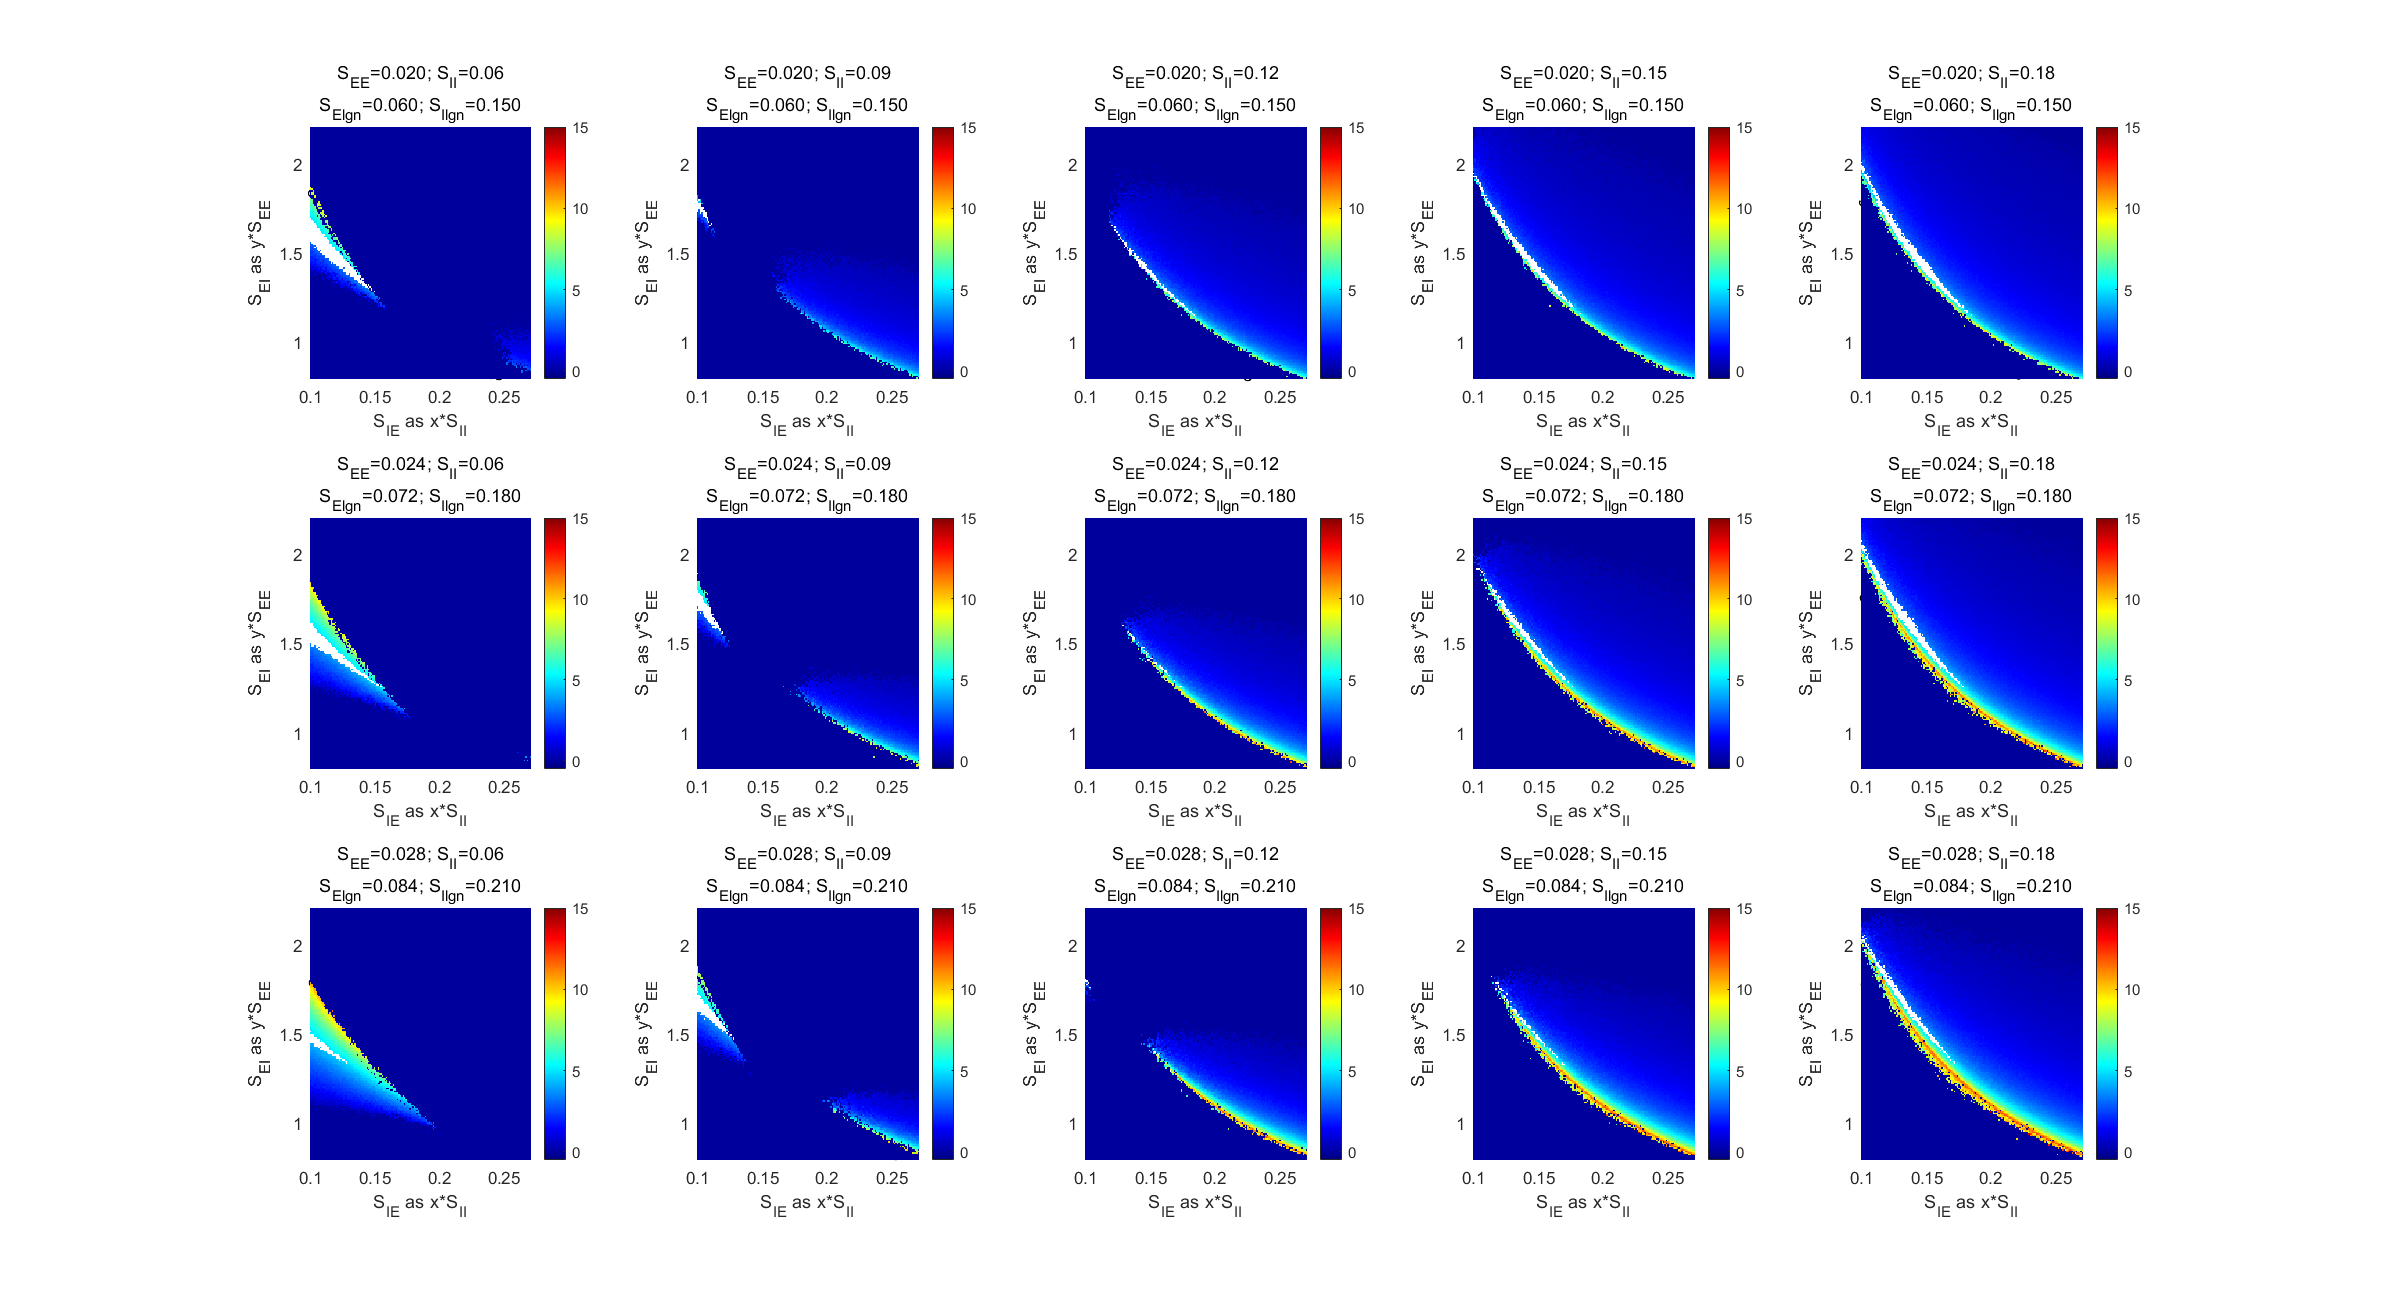

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [41.95,25.68];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[MF_7Dpath FigName1 '.pdf'],'Resolution',600)

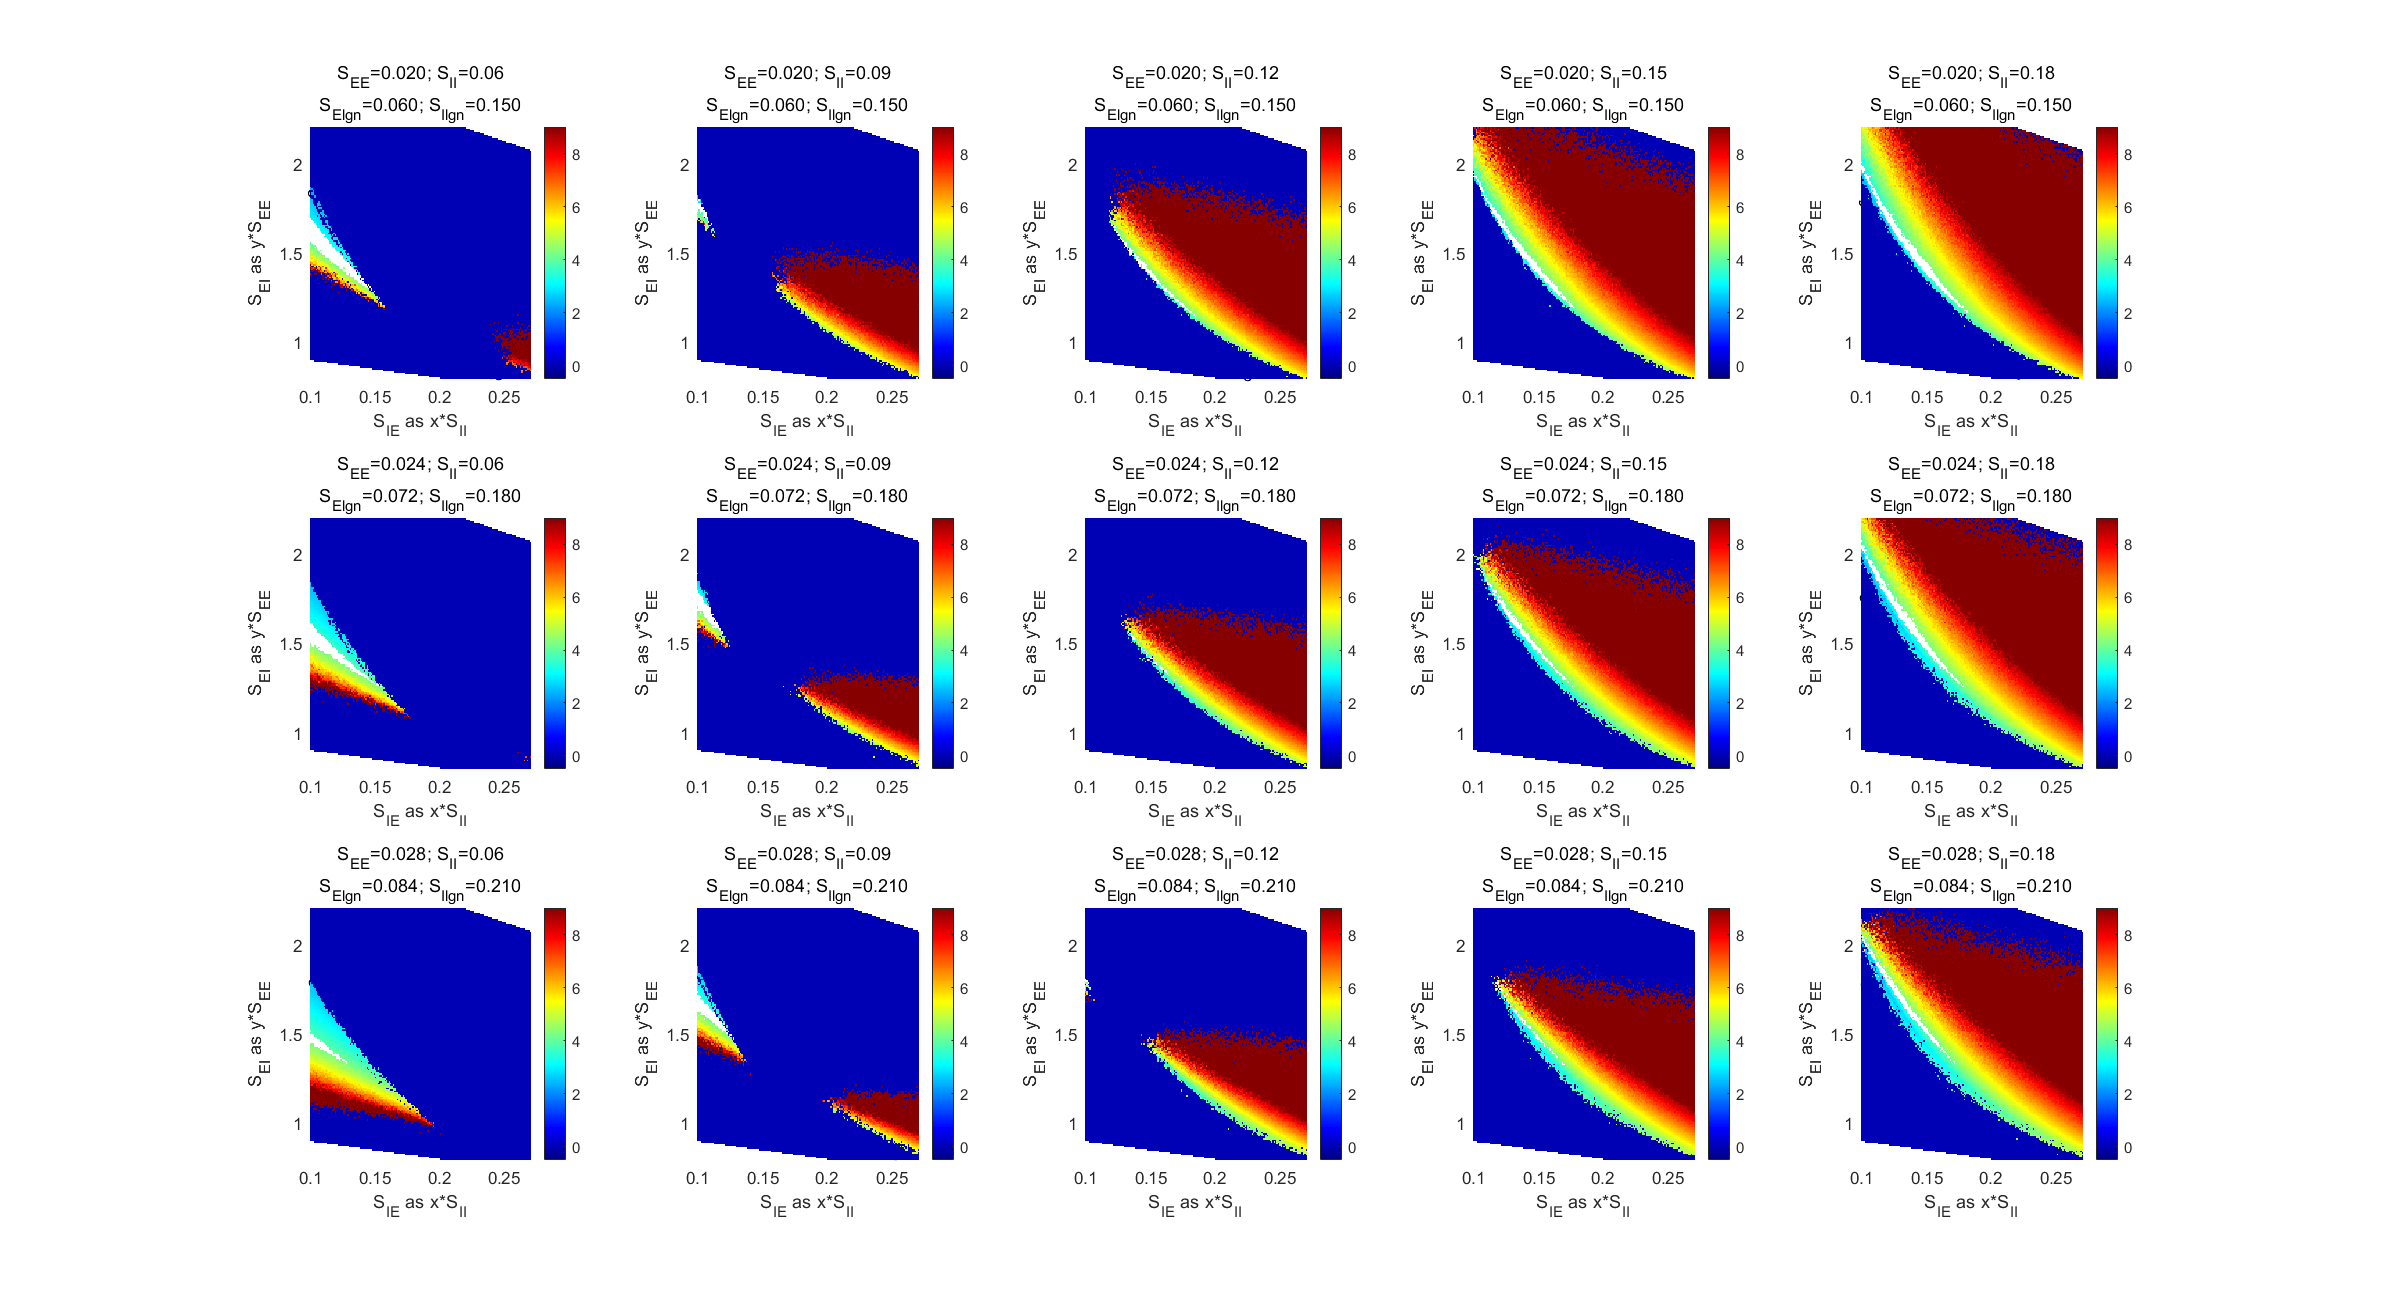

exportgraphics(Fig2,[MF_7Dpath FigName2 '.pdf'],'Resolution',600)

## 5. Print parameters

sprintf(['S_EE = %.3f, S_II = %.3f, S_Elgn = %.3f, S_amb = %.3f, S_EL6 = %.3f, S_IL6 = %.3f\n',...
    'r_Elgn = %.3f, r_Ilgn = %.3f, r_Eamb = %.3f, r_Iamb = %.3f, r_EL6 = %.3f'],...
    ContourData_7D.S_EE, ContourData_7D.S_II, ContourData_7D.S_Elgn, ContourData_7D.S_amb, ContourData_7D.S_EL6, ContourData_7D.S_IL6,...
    ContourData_7D.lambda_E, ContourData_7D.lambda_I, ContourData_7D.rE_amb, ContourData_7D.rI_amb, ContourData_7D.rE_L6)

## 6. Current Decomposition for Specific Panels

S_EEInd = 2; S_IIInd = 1;
% DEtermine dependent parameters
S_EE = S_EEtest(S_EEInd);
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_Elgn=S_Elgntest(S_ElgnInd);

S_II = S_IItest(S_IIInd);
S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
S_Ilgn = S_Ilgntest(S_IlgnInd);

load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
                          S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
FrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
FrE(FrE<=0) = 0;
FrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
FrI(FrE<=0) = 0;
mVE = squeeze(ContourData_7D.mV_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
mVE(FrE<=0) = 0;
mVI = squeeze(ContourData_7D.mV_NoFix(2,:,: ));
mVI(FrE<=0) = 0;
Blowup = squeeze(ContourData_7D.FailIndi(:,: ));

GoodAreaInd = FrE>=3 & FrE<=5   & ...
              FrI./FrE    >=3   &   FrI./FrE    <=4.25;
% Take all values from the field
unpackStruct(ContourData_7D);          
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));  

% A few Ss is indexed to S_IE; and Ref on Fr; so need to prepared in advance
S_EIMat = repmat(S_EItest',1,length(S_IEtest));
S_IEMat = repmat(S_IEtest, length(S_EItest),1);
S_IL6 = 1/3*S_IEMat;
E_Refac = (1-FrE*tau_ref/1000); E_RefacInv = E_Refac.^-1;
I_Refac = (1-FrI*tau_ref/1000); I_RefacInv = I_Refac.^-1;        
          
% Compute total conductances
ENr.EExtCond = (lambda_E*S_Elgn + rE_amb*S_amb)*1000;         % External->E
ENr.ERecCond = N_EE*S_EE*(1-p_EEFail)*FrE + rE_L6*S_EL6*1000; % E Recurrent->E (L4+L6)
INr.EExtCond = (lambda_I*S_Ilgn + rI_amb*S_amb)*1000;         % External->I
INr.ERecCond = N_IE*S_IEMat         .*FrE + rI_L6*S_IL6*1000; % E Recurrent->I (L4+L6)  
        
ENr.ICond    = N_EI*S_EIMat.*FrI;                             % I Recurrent->E (L4) 
INr.ICond    = N_II*S_II    *FrI;                             % I Recurrent->I (L4) 

ENr.LCond    = gL_E*1000;
INr.LCond    = gL_I*1000;

%% This is what it supposed to be!!
% Compute total current 
ENr.EExtCurr = ENr.EExtCond * (Ve-mVE); % External   ->E
ENr.ERecCurr = ENr.ERecCond.* (Ve-mVE); % E Recurrent->E (L4+L6)
ENr.ICurr    = ENr.ICond   .* (Vi-mVE); % I Recurrent->E (L4) 
ENr.LCurr    = ENr.LCond   .* (0 -mVE);

INr.EExtCurr = INr.EExtCond * (Ve-mVI); % External   ->I
INr.ERecCurr = INr.ERecCond.* (Ve-mVI); % E Recurrent->I (L4+L6)         
INr.ICurr    = INr.ICond   .* (Vi-mVI); % I Recurrent->I (L4) 
INr.LCurr    = INr.LCond   .* (0 -mVI);

%% But Linear transfer with fake Ref setup
E_All = E_Refac .* (ENr.ERecCurr.*E_RefacInv + ENr.ICurr.*I_RefacInv + ENr.EExtCurr + ENr.LCurr);
I_All = I_Refac .* (INr.ERecCurr.*E_RefacInv + INr.ICurr.*I_RefacInv + INr.EExtCurr + INr.LCurr);

## But since I made a tiny mistake in MF algorithms...

I have to let L6 not be counted as "recurrent"...

% Compute total conductances
ENr.EExtCond_Fk = (lambda_E*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6)*1000;         % External->E
ENr.ERecCond_Fk = full(N_EE)*S_EE*(1-p_EEFail)*FrE; % E Recurrent->E (L4+L6)
INr.EExtCond_Fk = (lambda_I*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6)*1000;         % External->I
INr.ERecCond_Fk = full(N_IE)*S_IEMat         .*FrE; % E Recurrent->I (L4+L6)  
        
ENr.ICond_Fk    = full(N_EI)*S_EIMat.*FrI;                             % I Recurrent->E (L4) 
INr.ICond_Fk    = full(N_II)*S_II    *FrI;                             % I Recurrent->I (L4) 

ENr.LCond_Fk    = gL_E*1000;
INr.LCond_Fk    = gL_I*1000;

% Compute total current 
ENr.EExtCurr_Fk = ENr.EExtCond_Fk * (Ve-mVE); % External   ->E
ENr.ERecCurr_Fk = ENr.ERecCond_Fk.* (Ve-mVE); % E Recurrent->E (L4+L6)
ENr.ICurr_Fk    = ENr.ICond_Fk   .* (Vi-mVE); % I Recurrent->E (L4) 
ENr.LCurr_Fk    = ENr.LCond_Fk   .* (0 -mVE);

INr.EExtCurr_Fk = INr.EExtCond_Fk.* (Ve-mVI); % External   ->I
INr.ERecCurr_Fk = INr.ERecCond_Fk.* (Ve-mVI); % E Recurrent->I (L4+L6)         
INr.ICurr_Fk    = INr.ICond_Fk   .* (Vi-mVI); % I Recurrent->I (L4) 
INr.LCurr_Fk    = INr.LCond_Fk   .* (0 -mVI);


E_All_Fk = E_Refac .* (ENr.ERecCurr_Fk.*E_RefacInv + ENr.ICurr_Fk.*I_RefacInv + ENr.EExtCurr_Fk + ENr.LCurr_Fk);
I_All_Fk = I_Refac .* (INr.ERecCurr_Fk.*E_RefacInv + INr.ICurr_Fk.*I_RefacInv + INr.EExtCurr_Fk + INr.LCurr_Fk);

## 7. Current Images

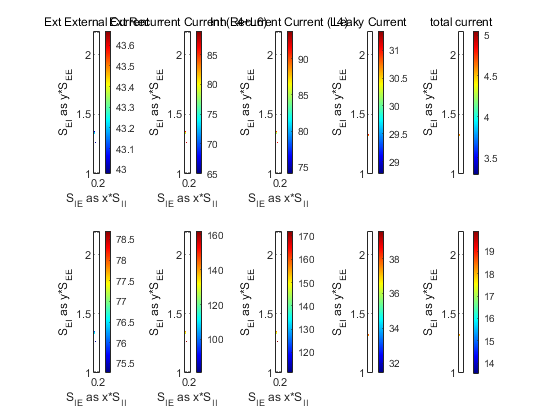

figure('Name','Currents')

subplot 251
EE_Ext  = ENr.EExtCurr .* E_Refac; EE_Ext(~GoodAreaInd) = nan; EE_Ext(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, EE_Ext);
subplot 256
IE_Ext  = INr.EExtCurr .* I_Refac; IE_Ext(~GoodAreaInd) = nan; IE_Ext(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, IE_Ext);

subplot 252
EE_Rec  = ENr.ERecCurr .* E_Refac; EE_Rec(~GoodAreaInd) = nan; EE_Rec(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, EE_Rec);
subplot 257
IE_Rec  = INr.ERecCurr .* I_Refac; IE_Rec(~GoodAreaInd) = nan; IE_Rec(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, IE_Rec);

subplot 253
EI_Rec  = ENr.ICurr .* E_Refac; EI_Rec(~GoodAreaInd) = nan; EI_Rec(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, abs(EI_Rec));
subplot 258
II_Rec  = INr.ICurr .* I_Refac; II_Rec(~GoodAreaInd) = nan; II_Rec(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, abs(II_Rec));

subplot 254
E_Leak  = ENr.LCurr .* E_Refac; E_Leak(~GoodAreaInd) = nan; E_Leak(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, abs(E_Leak));
subplot 259
I_Leak  = INr.LCurr .* I_Refac; I_Leak(~GoodAreaInd) = nan; I_Leak(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, abs(I_Leak));

% E_All = E_All_Fk;
% I_All = I_All_Fk;
subplot 255
%E_All  = EE_Ext + EE_Rec + EI_Rec + E_Leak;
E_All(~GoodAreaInd) = nan;  E_All(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, E_All);
subplot (2,5,10)
%I_All  = IE_Ext + IE_Rec + II_Rec + I_Leak;
I_All(~GoodAreaInd) = nan;  I_All(Blowup==1) = nan;
imagesc(S_IEtest/S_II, S_EItest/S_EE, I_All);

for PlotInd = 1:10
    subplot(2,5,PlotInd)
    set(gca,'YDir','Normal')
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    cmap = [1,1,1; jet];
    colormap(cmap); colorbar;
    axis([0.11 0.23 1 2.2])
end

subplot 251
title('Ext External Current')
subplot 252
title('Ext Recurrent Current (L4+L6)')
subplot 253
title('Inh Recurrent Current (L4)')
subplot 254
title('Leaky Current')
subplot 255
title('total current')

## 8. Current diff for all panels in one fig

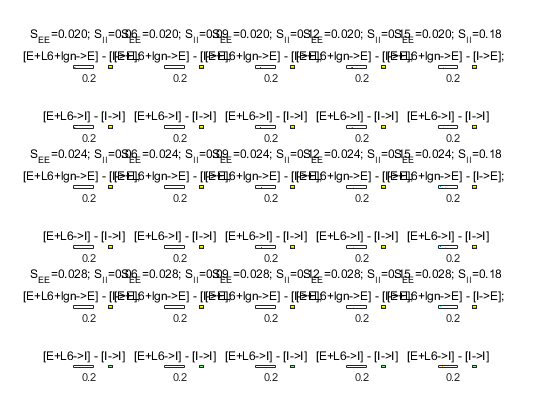

figure('NAme','Current Diff')
for S_EEInd = 1:length(S_EEtest)
    for S_IIInd = 1:length(S_IItest)
        % DEtermine dependent parameters
        S_EE = S_EEtest(S_EEInd);
        S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
        S_Elgn=S_Elgntest(S_ElgnInd);
        
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('ContourData_S_EE=%.3f_S_II=%.2f_S_Elgn=%.3f_7D_HPC_S_IlgnInd%d_rI_L6Ind%d.mat',...
            S_EE,     S_II,     S_Elgn,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        S_EEtest = [0.020 0.024 0.028];
        FrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        FrE(FrE<=0) = 0;
        FrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        FrI(FrE<=0) = 0;
        mVE = squeeze(ContourData_7D.mV_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        mVE(FrE<=0) = 0;
        mVI = squeeze(ContourData_7D.mV_NoFix(2,:,: ));
        mVI(FrE<=0) = 0;
        Blowup = squeeze(ContourData_7D.FailIndi(:,: ));
        
        GoodAreaInd = FrE>=3 & FrE<=5   & ...
            FrI./FrE    >=3   &   FrI./FrE    <=4.25;
        % Take all values from the field
        unpackStruct(ContourData_7D);
        E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
        [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
        E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
        
        I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
        [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
        I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
        
        N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
        N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));
        
        % A few Ss is indexed to S_IE; and Ref on Fr; so need to prepared in advance
        S_EIMat = repmat(S_EItest',1,length(S_IEtest));
        S_IEMat = repmat(S_IEtest, length(S_EItest),1);
        S_IL6 = 1/3*S_IEMat;
        E_Refac = (1-FrE*tau_ref/1000); E_RefacInv = E_Refac.^-1;
        I_Refac = (1-FrI*tau_ref/1000); I_RefacInv = I_Refac.^-1;
        
        % Compute total conductances
        ENr.EExtCond = (lambda_E*S_Elgn + rE_amb*S_amb)*1000;         % External->E
        ENr.ERecCond = N_EE*S_EE*(1-p_EEFail)*FrE + rE_L6*S_EL6*1000; % E Recurrent->E (L4+L6)
        INr.EExtCond = (lambda_I*S_Ilgn + rI_amb*S_amb)*1000;         % External->I
        INr.ERecCond = N_IE*S_IEMat         .*FrE + rI_L6*S_IL6*1000; % E Recurrent->I (L4+L6)
        
        ENr.ICond    = N_EI*S_EIMat.*FrI;                             % I Recurrent->E (L4)
        INr.ICond    = N_II*S_II    *FrI;                             % I Recurrent->I (L4)
        
        ENr.LCond    = gL_E*1000;
        INr.LCond    = gL_I*1000;
        
        %% This is what it supposed to be!!
        % Compute total current
        ENr.EExtCurr = ENr.EExtCond * (Ve-mVE); % External   ->E
        ENr.ERecCurr = ENr.ERecCond.* (Ve-mVE); % E Recurrent->E (L4+L6)
        ENr.ICurr    = ENr.ICond   .* (Vi-mVE); % I Recurrent->E (L4)
        ENr.LCurr    = ENr.LCond   .* (0 -mVE);
        
        INr.EExtCurr = INr.EExtCond * (Ve-mVI); % External   ->I
        INr.ERecCurr = INr.ERecCond.* (Ve-mVI); % E Recurrent->I (L4+L6)
        INr.ICurr    = INr.ICond   .* (Vi-mVI); % I Recurrent->I (L4)
        INr.LCurr    = INr.LCond   .* (0 -mVI);
        
        %% Sublots
        aa = length(S_EEtest);
        bb = length(S_IItest);
        
        subplot(aa*2,bb,S_IIInd+(S_EEInd-1)*2*bb)
        E_EminsI = ENr.ERecCurr + ENr.ICurr + lambda_E*S_Elgn*1000* (Ve-mVE);
        E_EminsI(~GoodAreaInd) = nan; E_EminsI(Blowup==1) = nan;
        imagesc(S_IEtest/S_II, S_EItest/S_EE, E_EminsI);
        set(gca,'YDir','Normal')
        %xlabel('S_{IE} as x*S_{II}'); ylabel('S_{EI} as y*S_{EE}')
        cmap = [1,1,1; jet]; colormap(cmap); colorbar;
        axis([0.11 0.23 1 2.2])
        title(sprintf('S_{EE}=%.3f; S_{II}=%.2f\n[E+L6+lgn->E] - [I->E]; ',...
                       S_EE,        S_II))
                   
        subplot(aa*2,bb,S_IIInd+(S_EEInd-1)*2*bb+bb)
        I_EminsI = INr.ERecCurr + INr.ICurr;
        I_EminsI(~GoodAreaInd) = nan; I_EminsI(Blowup==1) = nan;
        imagesc(S_IEtest/S_II, S_EItest/S_EE, I_EminsI);
        set(gca,'YDir','Normal')
        %xlabel('S_{IE} as x*S_{II}'); ylabel('S_{EI} as y*S_{EE}')
        cmap = [1,1,1; jet]; colormap(cmap); colorbar;
        axis([0.11 0.23 1 2.2])
        title('[E+L6->I] - [I->I]')
    end
end